### Init and load torque from excel:

clear
load("airfoil.mat")
load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
data = load("Wing_Load_Positive.mat")

data = struct with fields:
    data: [60×4 table]


y0 = [-flip(data.data.Var1); data.data.Var1(2:end)];
S0 = [flip(data.data.Var2); data.data.Var2(2:end)];
M0 = [flip(data.data.Var3); data.data.Var3(2:end)];
tau0 = [flip(data.data.Var4); data.data.Var4(2:end)];

M = interp1(y0, M0, wing_opt.stripy,'spline');
tau = interp1(y0, tau0, wing_opt.stripy,'spline');
S = interp1(y0, S0, wing_opt.stripy,'spline');

pltidx=1

pltidx = 1

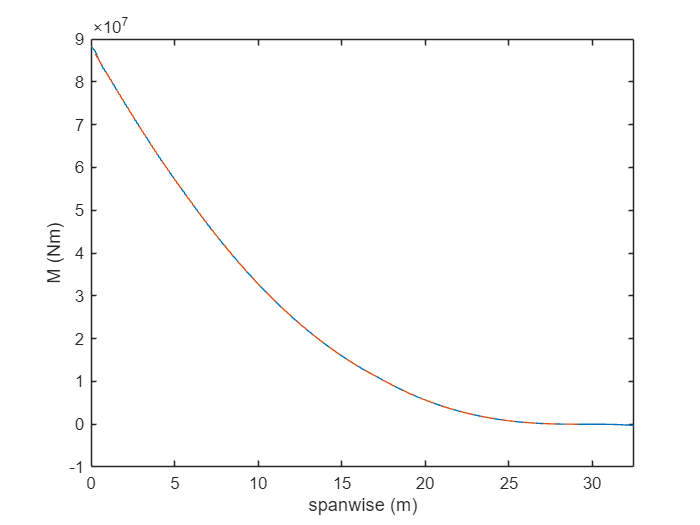

figure(pltidx)
clf;
plot(wing_opt.stripy, M)
hold on
plot(y0, M0,'--')
xlabel("spanwise (m)")
ylabel("M (Nm)")
xlim([0 wing_opt.b/2])

pltidx = pltidx + 1;

Material:

Al=material(); %Aluminum 2024 T861
Al.E = 72e9; %E - 72-75.7 GPa (@23degC is 73)
Al.sigma_y = 400e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al.G = 28e9; %G - 28-29.4 GPa

## **WingBox geometry (unchanged throughout)**

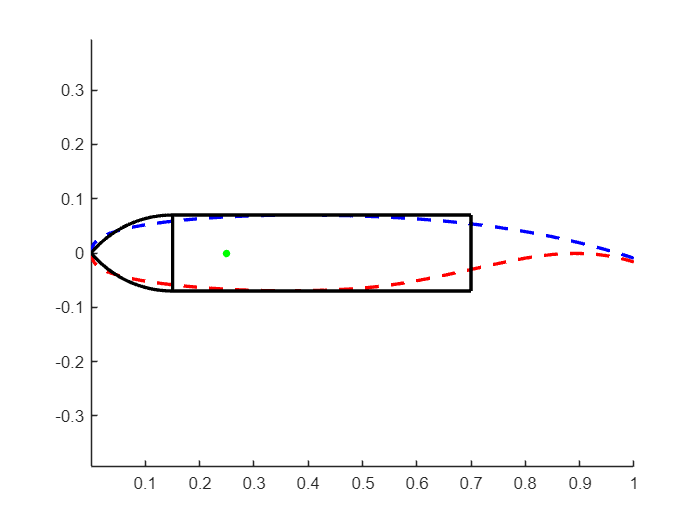

D = 6.38;
wb = wingbox();
%define geometry
wb.b2_c = 0.14;
wb.b_c = 0.15;
wb.c_c = 0.7 - wb.b_c;
wb = wb.calcR();
%define stringers
wb.L = 1;
%show wingbox:
figure(pltidx)
clf;
wb.drawwithAirfoil(airfoil)

pltidx = pltidx + 1;

wb = wb.calcCellArea(wing_opt);

%define rib spacing
wb.a = ones(1,length(wing_opt.stripy)).*5;
wingidx = find(wing_opt.stripy > D/2); % only consider points on the wing

spar geometry, flange

wb.t1_spar = 2e-3;
wb.t2_spar = 2e-3;
wb.b_spar = 10e-3;
wb = wb.createRibs(20, wing_opt, D, "uniform")

wb =   wingbox with properties:

        t_D: []
    t_Upper: []
    t_Lower: []
         tF: []
         tR: []
        c_c: 0.5500
       b1_c: []
        b_c: 0.1500
        R_c: 0.1957
          a: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 … ] (1×301 double)
       b2_c: 0.1400
         ts: []
         ds: []
         hs: []
         As: []
      sr_s0: []
          N: []
          F: []
    t1_spar: 0.0020
    t2_spar: 0.0020
     b_spar: 0.0100
         An: [0.1788 0.1852 0.1918 0.1985 0.2053 0.2122 0.2193 0.2264 0.2337 0.2411 0.2486 0.2562 0.2640 0.2718 0.2798 0.2878 0.2960 0.3043 0.3128 0.3213 0.3299 0.3387 0.3476 0.3566 0.3657 0.3749 0.3843 0.3937 0.4033 0.4130 0.4228 … ] (1×301 double)
         Ar: [0.9432 0.9774 1.0121 1.0475 1.083

wb = wb.mapRibSpacing(wing_opt, D)

wb =   wingbox with properties:

        t_D: []
    t_Upper: []
    t_Lower: []
         tF: []
         tR: []
        c_c: 0.5500
       b1_c: []
        b_c: 0.1500
        R_c: 0.1957
          a: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 … ] (1×301 double)
       b2_c: 0.1400
         ts: []
         ds: []
         hs: []
         As: []
      sr_s0: []
          N: []
          F: []
    t1_spar: 0.0020
    t2_spar: 0.0020
     b_spar: 0.0100
         An: [0.1788 0.1852 0.1918 0.1985 0.2053 0.2122 0.2193 0.2264 0.2337 0.2411 0.2486 0.2562 0.2640 0.2718 0.2798 0.2878 0.2960 0.3043 0.3128 0.3213 0.3299 0.3387 0.3476 0.3566 0.3657 0.3749 0.3843 0.3937 0.4033 0.4130 0.4228 … ] (1×301 double)
         Ar: [0.9432 0.9774 1.0121 1.0475 1.083

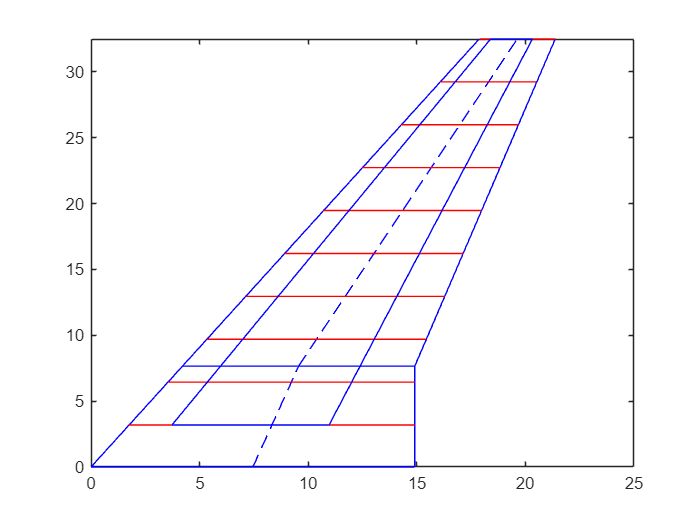


figure(pltidx)
clf;
pltidx = pltidx + 1;
wing_opt.plotWing
hold on
wb.plotRibs(wing_opt)
hold on
wb.plotWingBox(wing_opt,D)
ylim([0 wing_opt.b/2])

## 1.UpperPanel Design

To get a high Farror ratio 0.95:

ts/t = 1.05

As/b1 t = 1.5

lb = [0.5e-3 0.5e-3 0.5e-3];%[ts, t, h_s]
ub = [10e-3 10e-3 100e-3];
step = 2e-3;
dy = wing_opt.stripy(2) - wing_opt.stripy(1);
c = wb.c_c.*wing_opt.cn;
b2 = wb.b2_c.*wing_opt.cn;
N = M./c./b2;
E = Al.E

E = 7.2000e+10

%init storage of result
bestts = Inf*ones(size(wing_opt.stripy));
bestt = Inf*ones(size(wing_opt.stripy));
besths = Inf*ones(size(wing_opt.stripy));

A_c2 = Inf*ones(size(wing_opt.stripy));
Vbest = Inf;
A_c2fun = @(b1, c, ts, hs, ds, t) (c/b1 - 1/c^2)*ts*hs*(1+2*ds/hs) + t/c;
for tsj = lb(1):step:ub(1)
    for tj = lb(2):step:ub(2)
        for hsj = lb(3):step:ub(3)
            thists = Inf*ones(size(wing_opt.stripy));
            thist = Inf*ones(size(wing_opt.stripy));
            thishs = Inf*ones(size(wing_opt.stripy));
            for i = 1:length(wing_opt.stripy)
                if wing_opt.stripy(i) > D/2 && N(i) > 0
                    [b1, ds] = computeAllGeometry(tsj,tj, hsj, E, N(i));
                    c = wing_opt.cn(i);
                    A_c2(i) = A_c2fun(b1, c, tsj, hsj, ds, tj);
                    thists(i) = tsj;
                    thist(i) = tj;
                    thishs(i) = hsj;
                end
            end
            V = sum(~isinf(~isnan(A_c2.*wing_opt.cn)));
            if V < Vbest
                Vbest = V;
                bestts = thists;
                bestt = thist;
                besths = thishs;
            end
            
            A_c2 = Inf*ones(size(wing_opt.stripy));
        end
        disp(V)
    end
end

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301

   301





function [b1, ds,L] = computeAllGeometry(ts,t,h_s, E, N)
    sigma0 = N/t;
    b1 = t*sqrt(3.62*E/sigma0);
    %interpolate F and scr_s0
    d_hratio = 0.3;
    ds = d_hratio * h_s;
    As = ts*h_s*(1 + 2*(d_hratio));
    As_bt = As/b1/t;
    ts_t = ts/t;
    F = interpF(As_bt, ts_t);
    sr_s0 = interpsr_s0(As_bt, ts_t);
    L = N*E*(sigma0/F)^2;
end


% Precompute parameters
c = wb.c_c .* wing_opt.cn;
b2 = wb.b2_c .* wing_opt.cn;
N = M ./ c ./ b2;
E = Al.E;
sigmaY = Al.sigma_y;

% Initialize optimal parameter vectors
bestt = zeros(size(wing_opt.stripy));
besths = zeros(size(wing_opt.stripy));

% Precompute ts_t and As_bt for all strips (example value: 1.2)
[As_bt, ts_t] = inverse_interpsr_s0(1);
F = interpF(As_bt, ts_t);

for i = 1:length(wing_opt.stripy)
    lb = [0.5e-3, 0.5e-3];  % Lower bounds [t, h_s]
    ub = [100e-3, 100e-3];    % Upper bounds
    
    if wing_opt.stripy(i) > D/2 && N(i) > 0
        % Initial guess (midpoint of bounds)
        x0 = [(lb(1) + ub(1))/2, (lb(2) + ub(2))/2];
        
        % Define local optimization problem
        localFun = @(x) localObjective(x, wing_opt.cn(i), ts_t, As_bt);
        
        % Define constraint function for yield conditions
        constraintFun = @(x) yieldConstraints(x, N(i), sigmaY, ts_t);
        
        % Solve with fmincon
        options = optimoptions('fmincon', 'Display', 'off', 'Algorithm', 'sqp');
        x_opt = fmincon(localFun, x0, [], [], [], [], lb, ub, constraintFun, options);
        
        % Store results
        bestt(i) = x_opt(1);
        besths(i) = x_opt(2);
    else
        % Default values for non-optimized strips
        bestt(i) = lb(1);
        besths(i) = lb(2);
    end
    disp(i);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125




%--- Local Objective Function (Unchanged) ---
function f = localObjective(x, c_i, ts_t, As_bt)
    t = x(1);
    h_s = x(2);
    d_h = 0.3;
    ts = t * ts_t;
    b1 = ts_t * h_s * (1 + 2*d_h) / As_bt;
    
    %objective function
    A_c2 = (c_i/b1 - 1/c_i^2) * ts * h_s * (1 + 2*d_h) + t/c_i;
    f = A_c2;
end

%--- Yield Constraint Function ---
function [c, ceq] = yieldConstraints(x, N_i, sigmaY, ts_t)
    t = x(1);  % Skin thickness
    ts = t * ts_t;  % Stringer thickness
    
    % Inequality constraints (yield conditions)
    c = [N_i / sigmaY - t;   % t >= N_i / sigmaY
         N_i / sigmaY - ts]; % ts >= N_i / sigmaY
    
    % No equality constraints
    ceq = [];
end

%--- Post-processing ---
sigma0 = N ./ bestt;
wb.L = (sigma0 ./ F).^(-2) .* N .* E;
wb.ts = bestt .* ts_t;
wb.t_Upper = bestt;
wb.hs = besths;

for i = 1:length(wb.hs)
    if N(i) > 0
        [b1, ds, L] = computeAllGeometry(wb.ts(i), wb.t_Upper(i), wb.hs(i), E, N(i));
    else
        b1 = 0;
        ds = 0;
        L = 0;
    end
    wb.L(i) = L;
    wb.b1_c(i) = b1 / c(i);
end

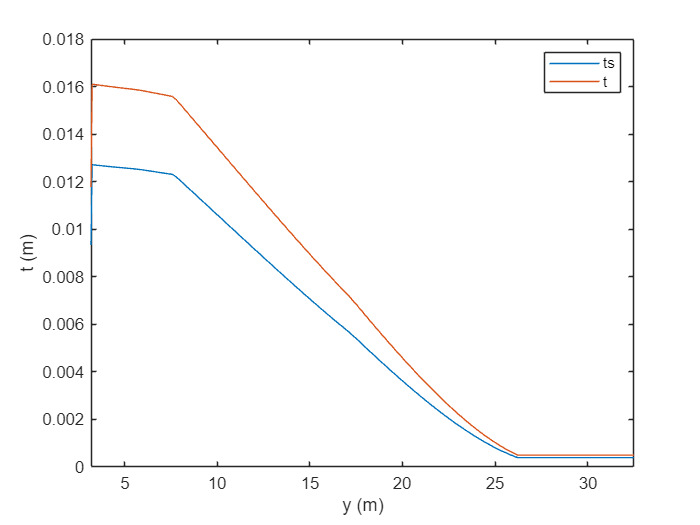

figure(1)
clf;
plot(wing_opt.stripy,wb.ts)
hold on
plot(wing_opt.stripy,wb.t_Upper)
xlim([D/2, wing_opt.b/2])
ylabel("t (m)")
xlabel("y (m)")
legend("ts", "t")

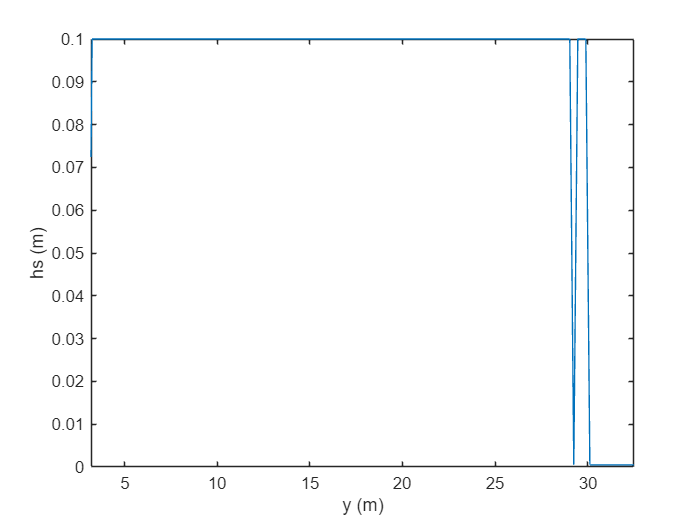


figure(2)
clf;
plot(wing_opt.stripy, wb.hs)
xlim([D/2, wing_opt.b/2])
ylabel("hs (m)")
xlabel("y (m)")

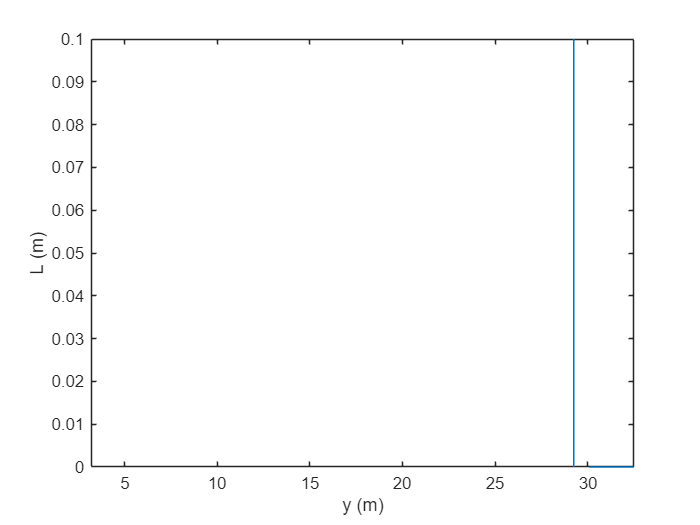


figure(3)
clf;
plot(wing_opt.stripy, wb.L)
xlim([D/2, wing_opt.b/2])
ylabel("L (m)")
xlabel("y (m)")
ylim([0 0.1])

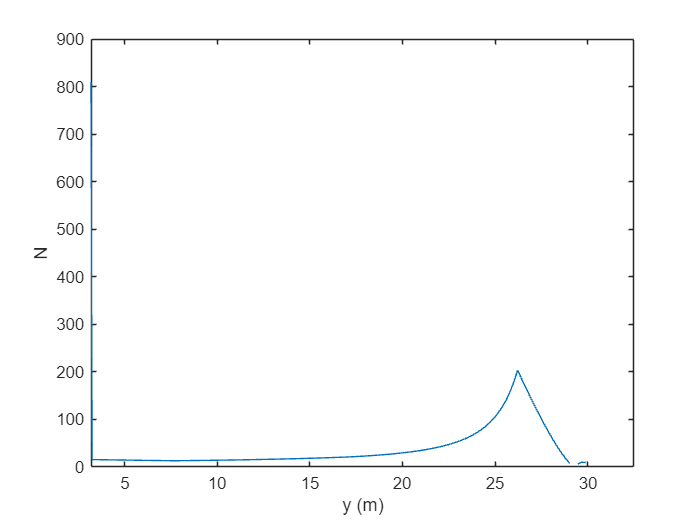


figure(4)
clf;
plot(wing_opt.stripy, 1./wb.b1_c)
xlim([D/2, wing_opt.b/2])
ylabel("N")
xlabel("y (m)")

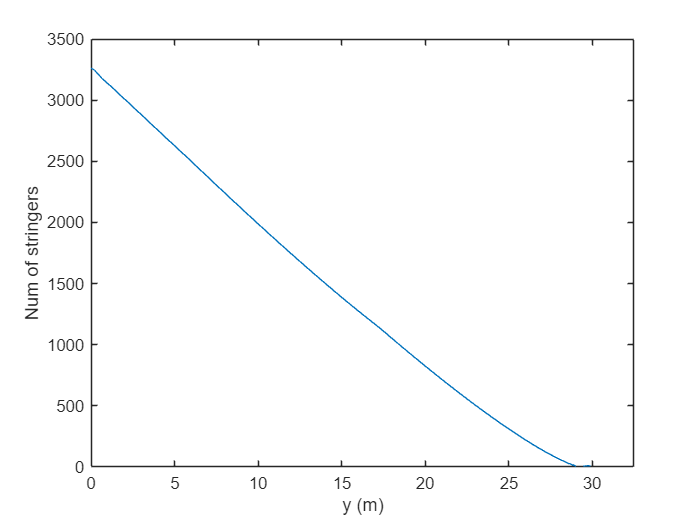

d_hratio = 0.3;
wb.ds = wb.hs*d_hratio;
wb = wb.calcStringerArea();
wb = wb.interpsr_s0(scr_s0,wing_opt);
wb = wb.interpretF(F_data, wing_opt);
ts = wb.ts;
t = wb.t_Upper;
hs = wb.hs;
b1_c = wb.b1_c;



pltidx = 1;
wbStress = wingboxStress();
wbStress.wb = wb;
wbStress = wbStress.findGlobalStress(M,wing_opt,Al, wb.t_Upper);
wbStress = wbStress.findLocalStress(M,wing_opt,Al);

Thickness parameters need to be optimized to give equal global and local buckling stress

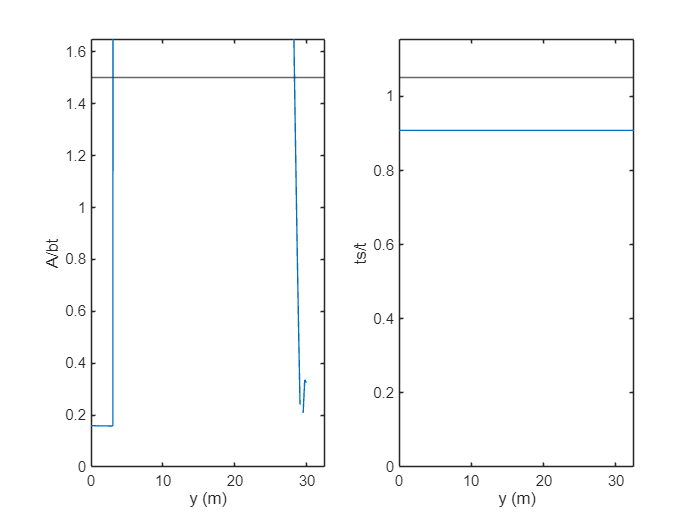

figure(2)
clf;
subplot(1,2,1)
xq = wb.As ./ (wb.b1_c .* wing_opt.cn) ./ wb.t_Upper;
yq = wb.ts/wb.t_Upper.*ones(size(xq));
plot(wing_opt.stripy,xq)
hold on
yline(1.5)
ylabel("A/bt")
xlabel("y (m)")
xlim([0 wing_opt.b/2])
ylim([0 1.5*1.1])

subplot(1,2,2)
plot(wing_opt.stripy,yq)
hold on
yline(1.05)
ylabel("ts/t")
xlabel("y (m)")
xlim([0 wing_opt.b/2])
ylim([0 1.05*1.1])

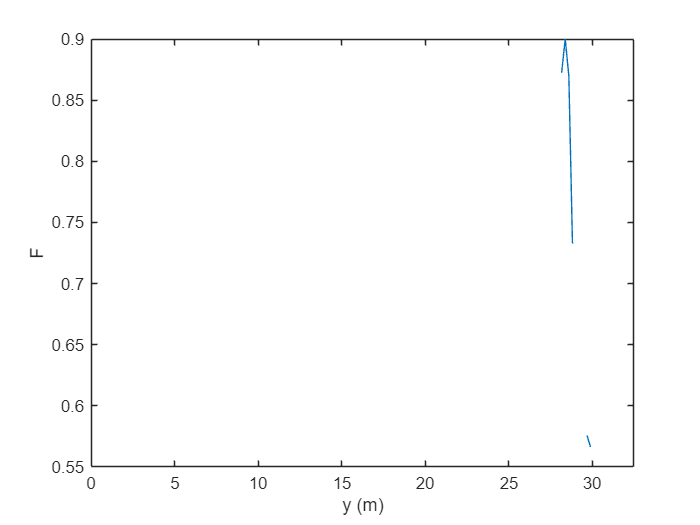



figure(3)
clf;
plot(wing_opt.stripy,wb.F)
ylabel("F")
xlabel("y (m)")
xlim([0 wing_opt.b/2])


figure(4)
clf;
pltidx = pltidx + 1;
hold on
plot(wing_opt.stripy(wingidx), wbStress.s_cr_global_skin(wingidx)*1e-6);
hold on
plot(wing_opt.stripy(wingidx), wbStress.s_cr_local_skin(wingidx)*1e-6);

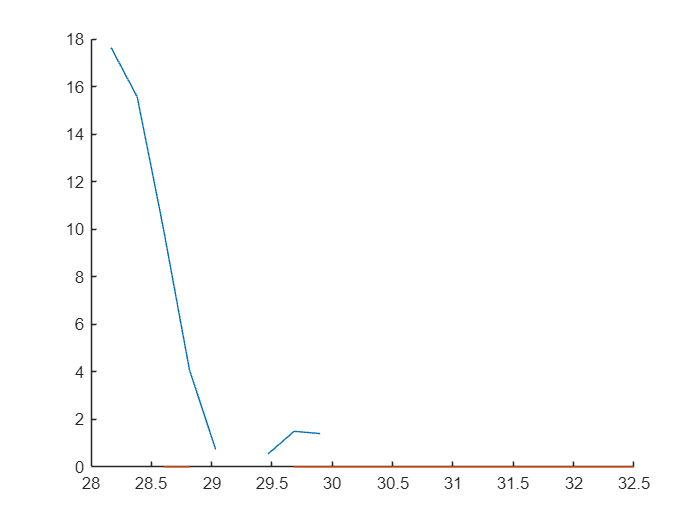

hold on

c = wb.c_c.*wing_opt.cn;
b2 = wb.b2_c.*wing_opt.cn;
N = M./c./b2;
plot(wing_opt.stripy(wingidx),N(wingidx)./wb.t_Upper*1e-6)

Arrays have incompatible sizes for this operation.

Related documentation

hold on
yline(Al.sigma_y*1e-6)
legend("Global Buckling","Local Buckling","Load","Yield Stress","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
ylabel("$\sigma$ (MPa)","Interpreter","latex")
xlim([0 wing_opt.s])
ylim([0 Al.sigma_y*1e-6*1.1])

## **2. Spar buckling analysis(get spar thickness)**

**Web is fixed at top/bottom, SS at sides (web stringers)**

[t_FS, t_RS] = Sparfun(wb, wing_opt,material,V,T,wbStress)

## 3. Dcell

%guessed D cell skin thickness
t1 = 0.01;
t = Dcellfun(wb,wing_opt,wing_opt.b/2,Al,t1,9)

## **4. Rib**

[thickness_buckling, thickness_yield]= Ribfun(20e-3,M,wing_opt,wb,Al,1e-3)

## 5. Box

P = rand(size(M))
[tau_n, tau_r, tau_w, sigmax] = boxfun(wb, wing_opt, P, M, Al)